# **IO753 & IO754 - Modbus TCP Loopback**

The IO753 and IO754 I/O modules are Modbus TCP modules to connect real-time target machines to external industrial devices such as motor controllers, sensors, I/O stations and robots.

The IO753 handles the complete data exchange between the connected Modbus TCP Servers and the real-time application. The data exchange is  processed via a dual-port memory. The module acts as one Modbus TCP Client exclusively. The IO754 handles the complete data exchange between the connected Modbus TCP Client and the real-time application. The data exchange is processed via a dual-port memory. The module acts as one Modbus TCP Server exclusively.

These I/O modules are ideal for rapid control prototyping of industrial devices such as programmable logic controllers (PLC), hardware-in-the-loop simulations, virtual commissioning, and factory acceptance tests using MATLAB® and Simulink®.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO753 and one IO754 installed

- CAT5 Ethernet cable or newer

### Pin Mapping/Connection Diagram/Test Setup

Modbus TCP is an Ethernet-based protocol. Use a CAT5 cable or newer to connect the IO753 with the IO754. Both modules have 2 connectors. It does not matter which one you use.

## Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_IO753_IO754_ModbusTCP_Loopback';
open_system(modelName);

## Model Description

The model sets up the communication for both the IO753 and IO754. When starting the model, the Setup blocks load the parameters configured in the block masks. The Receive and Send blocks are used to exchange data.

The IO753 is configured to send 14 bytes to the IO754. Within this payload, the data is structured as followed:

- Constant signal of type double

- Counter signal of type uint16

- Sine wave of type double

- Square signal of type uint16

The model illustrates how to use [Byte Packing](https://www.mathworks.com/help/slrealtime/io_ref/bytepacking.html) blocks to pack the signals into one byte array to be processed by the Send block. [Byte Unpacking](https://www.mathworks.com/help/slrealtime/io_ref/byteunpacking.html) blocks are used to extract the signals from the byte array that the Receive block outputs.

The IO754 is configured to send 14 bytes to the IO753. Within this payload, the data is structured as followed:

- Constant signal of type uint16

- Counter signal of type uint16

- Sine wave of type double

- Square signal of type uint16

The Simulink model features the Ethernet protocol blocks from the [speedgoatlib_IO753](matlab:open('https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io753')) and [speedgoatlib_IO754](matlab:open('https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io754')) libraries.

#### Configure Modbus TCP Client

The IP address of the** Modbus TCP Client** is specified in the [IO753 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io753_setup_v2) block and is configured with the help of the workspace variable` IP_Client_00.`

 
% Configure the IP addresse of the Modbus Client (IO753)
IP_Client_00 = '192.168.10.10';
speedgoat.model.highlight([modelName '/IO753 Modbus TCP - Client/IO753Setup'],'Parameter','parIpAddress');

#### Configure Modbus TCP Server

The IP address of the **Modbus TCP Server** is specified in the [IO754 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io754_setup_v2) block and is configured with the help of the workspace variable` IP_Server_00.`

 
% Configure the IP addresse of the Modbus Server (IO754)
IP_Server_00 = '192.168.10.20';
set_param([modelName '/IO754 Modbus TCP - Server/IO754Setup'],'ipAdr',IP_Server_00);
speedgoat.model.highlight([modelName '/IO754 Modbus TCP - Server/IO754Setup'],'Parameter','ipAdr');

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download the real-time application to the target machine
tg.load(modelName);

% Start the real-time application and open the SDI-Viewer
stoptime = 6; % Simulation length [s]
numsignals = 8; % Number of signals to be viewed in the SDI

Simulink.sdi.clear;
Simulink.sdi.view;

tg.setStopTime(stoptime);
tg.start;

runobj = Simulink.sdi.Run.getLatest;
sigsobj = runobj.getAllSignals;
for k = 1:numsignals % Display all signals in the plot
    sigsobj(k).Checked = 1;
end

pause(1)
Simulink.sdi.setSubplotLimits(1, 1, "tMin", 1, "tMax", stoptime, "yMin", -55, "yMax", 55);

The output is then visible in the Simulink Data Inspector (SDI). You should see 8 different signals, like in the image below (colors may vary):

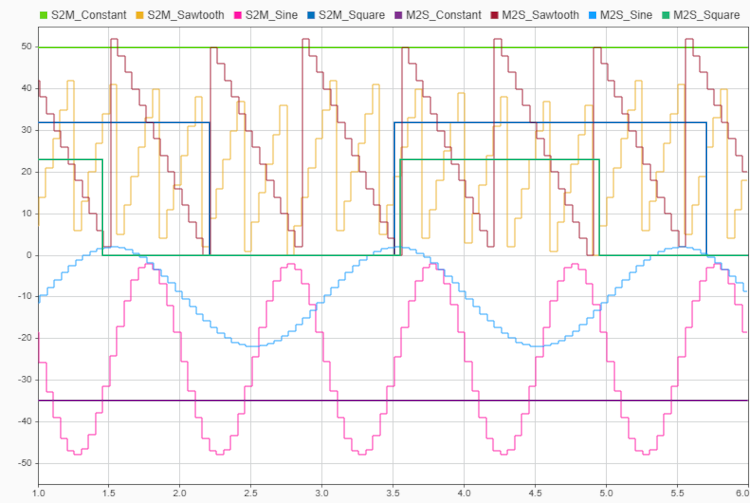

There is always a constant value, a counter (sawtooth), a square and a sine wave, from Client to Server (M2S) and from Server to Client (S2M).

## Additional References

- [IO753 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io753)

- [IO754 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io754)